clc
clear


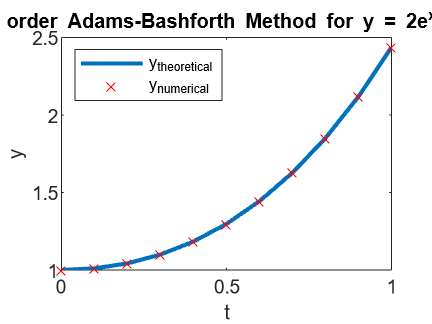

h = 0.1; n = 1/h;
k1 = zeros(1,2); k2 = zeros(1,2); k3 = zeros(1,2);
k4 = zeros(1,2); k5 = zeros(1,2); k6 = zeros(1,2);


yNumerical = zeros(1,2); yNumerical(1) = 1;
f(1) = 0;
t = 0:h:1;

syms T Y;
myFunction = Y+2*T-1;
yTheoretical = 2.*exp(t)-2.*t-1;

for i=1:2

    k1(i) = h*subs(myFunction , [T,Y],[t(i) , yNumerical(i)]);
    k2(i) = h*subs(myFunction , [T,Y],[t(i)+h/4 , yNumerical(i)+k1(i)/4]);
    k3(i) = h*subs(myFunction , [T,Y],[t(i)+3*h/8 , yNumerical(i)+3*k1(i)/32+9*k2(i)/32]);
    k4(i) = h*subs(myFunction , [T,Y],[t(i)+12*h/13 , yNumerical(i)+1932*k1(i)/2197-7200*k2(i)/2197+7296*k3(i)/2197]);
    k5(i) = h*subs(myFunction , [T,Y],[t(i)+h , yNumerical(i)+439*k1(i)/216-8*k2(i)+3680*k3(i)/513-845*k4(i)/4104]);
    k6(i) = h*subs(myFunction , [T,Y],[t(i)+h/2 , yNumerical(i)-8*k1(i)/27+2*k2(i)-3544*k3(i)/2565+1859*k4(i)/4104-11*k5(i)/40]);

    yNumerical(i+1) = yNumerical(i) + (16*k1(i)/165 + 6656*k3(i)/12825 + 28561*k4(i)/56430 - 9*k5(i)/50 + 2*k6(i)/55);
    f(i+1) = subs(myFunction , [T,Y],[t(i+1) , yNumerical(i+1)]);
end

for j=3:n
    yNumerical(j+1) = yNumerical(j) + h/12*(23*f(j) - 16*f(j-1) + 5*f(j-2));
    f(j+1) = subs(myFunction , [T,Y],[t(j+1) , yNumerical(j+1)]);
end

error = yTheoretical(end) - yNumerical(end);
errorPercentage = error./yTheoretical(end);


plot(t,yTheoretical,'LineWidth',2), hold on
plot(t,yNumerical, 'rx')
title("3^{rd} order Adams-Bashforth Method for y = 2e^{x}-2x-1")
xlabel("t"), ylabel("y")
legend("y_{theoretical}","y_{numerical}",'Location','northwest')